# Assignment 1: Optics / Snell

*Pratheep Kumar Chelladurai*

Please “check the math” on this. Assume the equilateral prism is made of flint glass, whose index of refraction *n* depends on wavelength according to the table below. The white light angle of incidence is 55° from normal.

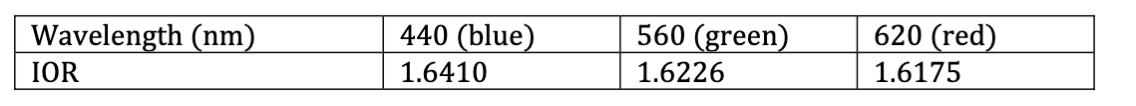

### Question 1a:

*What percent of the unpolarized incident light, at each wavelength, is reflected from the first surface of the prism (see Eqs 1.1-1.3)?*

n_material = [1.6410 1.6226 1.6175];
n_air = 1;
angle_incidence = 55;
surface_reflection = zeros(3,0);

for i = 1 : length(n_material)

r_parallel = ((cosd(angle_incidence) - ...
    sqrt((n_material(i)/n_air)^2 - sind(angle_incidence)^2)) ...
    / ...
    (cosd(angle_incidence) + ...
    sqrt((n_material(i)/n_air)^2 - sind(angle_incidence)^2)))^2 ;


r_perpendicular = ((((n_material(i)/n_air)^2)*(cosd(angle_incidence)) - ...
    sqrt((n_material(i)/n_air)^2 - sind(angle_incidence)^2)) ...
    / ...
    (((n_material(i)/n_air)^2)*(cosd(angle_incidence)) + ...
    sqrt((n_material(i)/n_air)^2 - sind(angle_incidence)^2)))^2 ;

surface_reflection(i) = ((r_parallel + r_perpendicular ) / 2) * 100;

end

surface_reflection_table = array2table(surface_reflection);
surface_reflection_table.Properties.VariableNames = {'Blue (in %)';...
    'Green (in %)';'Red (in %)'};
surface_reflection_table

surface_reflection_table = 1×3 table
    Blue (in %)    Green (in %)    Red (in %)
    ___________    ____________    __________

      9.1223          8.8461         8.7693  


### Question 1b:

*What are the three angles of transmission, corresponding to the tabulated wavelengths, inside the prism (see Snell’s Law, Eq 1.5)?*

angle_of_transmission = zeros(3,0);
for i = 1:length(n_material)
    angle_of_transmission(i) = asind((n_air/n_material(i))...
        *sind(angle_incidence));
end

angle_of_transmission_table = array2table(angle_of_transmission);
angle_of_transmission_table.Properties.VariableNames = {'Blue (in deg)';...
    'Green (in deg)';'Red (in deg)'};
angle_of_transmission_table

angle_of_transmission_table = 1×3 table
    Blue (in deg)    Green (in deg)    Red (in deg)
    _____________    ______________    ____________

       29.946            30.321           30.426   


### Question 1c:

*What are the three angles of exit from the prism?*

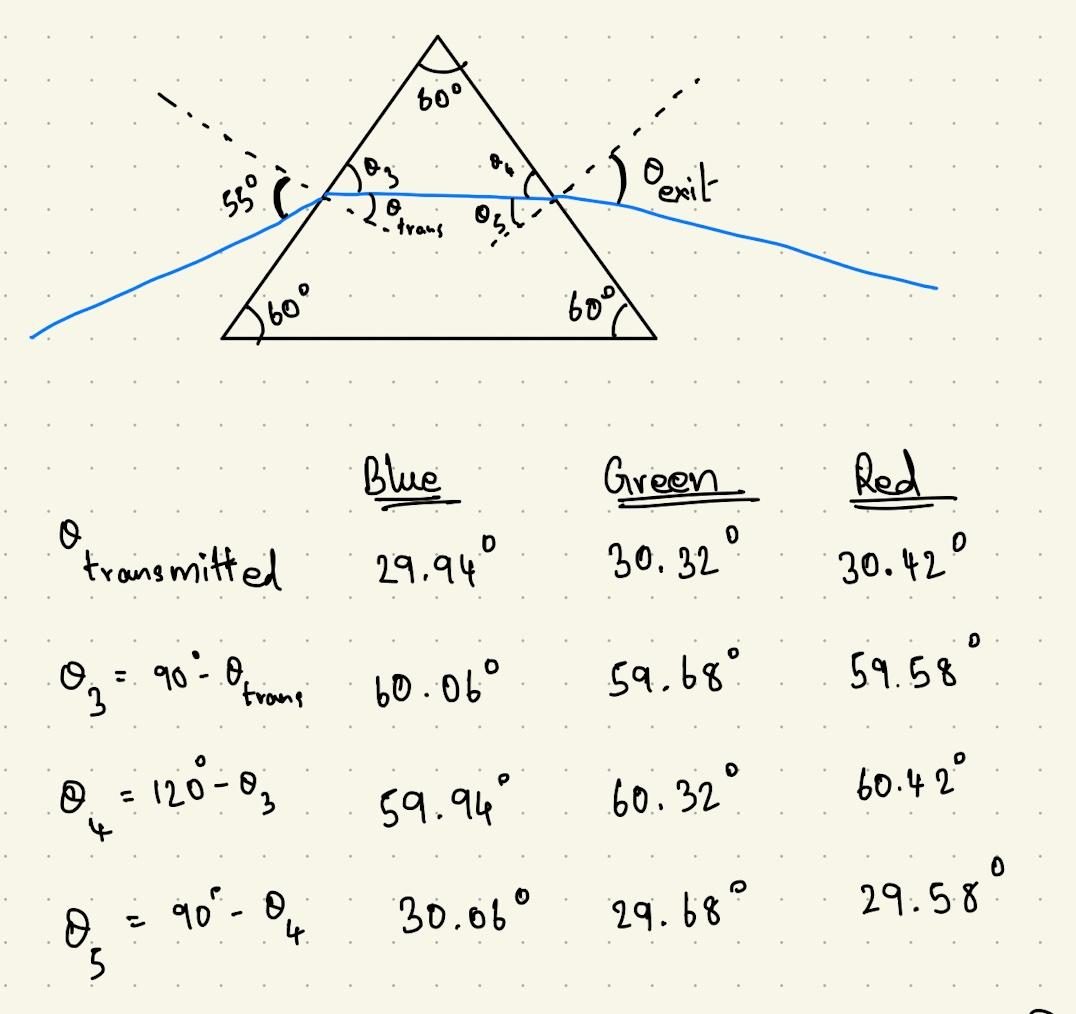

theta_5 = [30.06 29.68 29.58];
exit_angle = zeros(3,0);
for i = 1:length(n_material)
    exit_angle(i) = asind((n_material(i)*sind(theta_5(i)))/n_air);
end
exit_angle_table = array2table(exit_angle);
exit_angle_table.Properties.VariableNames = {'Blue (in deg)';...
    'Green (in deg)';'Red (in deg)'};
exit_angle_table

exit_angle_table = 1×3 table
    Blue (in deg)    Green (in deg)    Red (in deg)
    _____________    ______________    ____________

       55.284            53.46            52.983   


#### Question 1d:

*What happens if the angle of incidence is 25° from normal?*

angle_incidence = 25;
angle_of_transmission = zeros(3,0);
thetha_I = zeros(3,0);
critical_angle = zeros(3,0);

for i = 1:length(n_material)
    angle_of_transmission(i) = asind((n_air/n_material(i))...
        *sind(angle_incidence));
    thetha_I(i) = 60 - angle_of_transmission(i);
    critical_angle(i) = asind((n_air/n_material(i))*sind(90));

end

thetha_c_table = array2table([thetha_I; critical_angle]);
thetha_c_table.Properties.VariableNames = {'Blue (in deg)';...
    'Green (in deg)';'Red (in deg)'};
thetha_c_table.Properties.RowNames = {'thetha_I','Critical Angle'};
thetha_c_table

thetha_c_table = 2×3 table
                      Blue (in deg)    Green (in deg)    Red (in deg)
                      _____________    ______________    ____________

    thetha_I             45.076            44.903           44.854   
    Critical Angle       37.545            38.046           38.188   


On comparing the row 1 and row 2 from the above table, incidence angle is greater than critical angle. In such case, total internal reflection occurs. Therefor no light will pass through the exit.

#### Question 1e:

*Is The Dark Side of the Moon “correct”?*

No it is not accurate. Difference in angle of dispersion between the wavelengths will not be linear. The designer the poster might followed the same difference to make it visually consistent. The following image shows the mathematically corrected dispersion (left) vs the dispersion from the poster (right). Also, the light will be in the prism before dispersing again. But it is not depicted clearly in the prism.

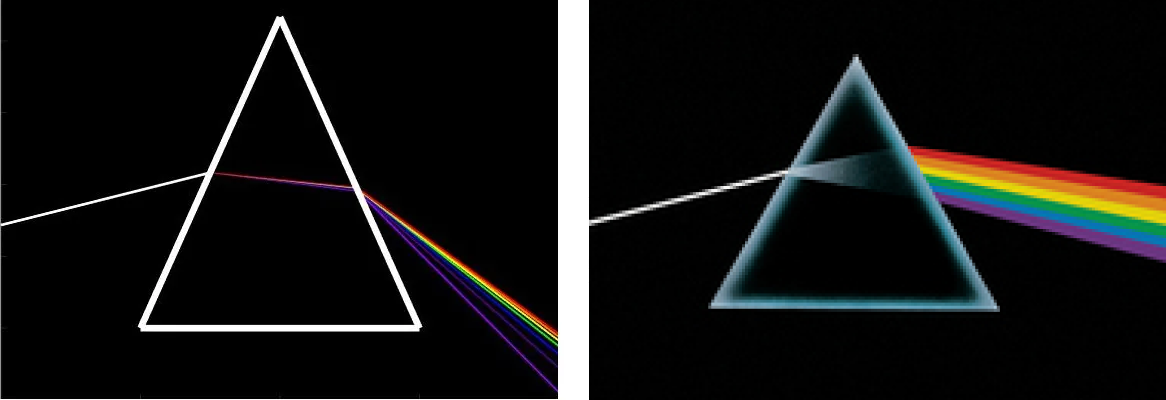

#### Question 1e:

*What’s your favorite song on this album?*

I haven't heard the album yet.

#### Question 2

*Consider a piece of black plastic with index of refraction n = 1.46. The front-surface reflection depends strongly on the angle of incidence*

**Question 2a**

*Compute the unpolarized front surface reflection in percent for angles of incidence of 0, 10, ..., 80° from normal, and plot the results as a function of angle*

n_material = 1.46;
n_air = 1;
surface_reflection = zeros(9,1);
angle_incidence = linspace(0,80,9);

for i = 1 : length(angle_incidence)
    r_parallel = ((cosd(angle_incidence(i)) - ...
        sqrt((n_material/n_air)^2 - sind(angle_incidence(i)) ^ 2)) ...
        / ...
        (cosd(angle_incidence(i)) + ...
        sqrt((n_material/n_air)^2 - sind(angle_incidence(i)) ^ 2)))^2 ;
    
    
    r_perpendicular = ((((n_material/n_air)^2)*(cosd(angle_incidence(i))) - ...
        sqrt((n_material/n_air)^2 - sind(angle_incidence(i)) ^ 2)) ...
        / ...
        (((n_material/n_air)^2)*(cosd(angle_incidence(i))) + ...
        sqrt((n_material/n_air)^2 - sind(angle_incidence(i)) ^ 2)))^2 ;
    
   surface_reflection(i) = ((r_parallel + r_perpendicular ) / 2) * 100;
end

array2table(surface_reflection)

ans = 9×1 table
    surface_reflection
    __________________

          3.4966      
           3.498      
          3.5215      
          3.6398      
          4.0391      
          5.1825      
          8.2454      
          16.325      
          38.043      


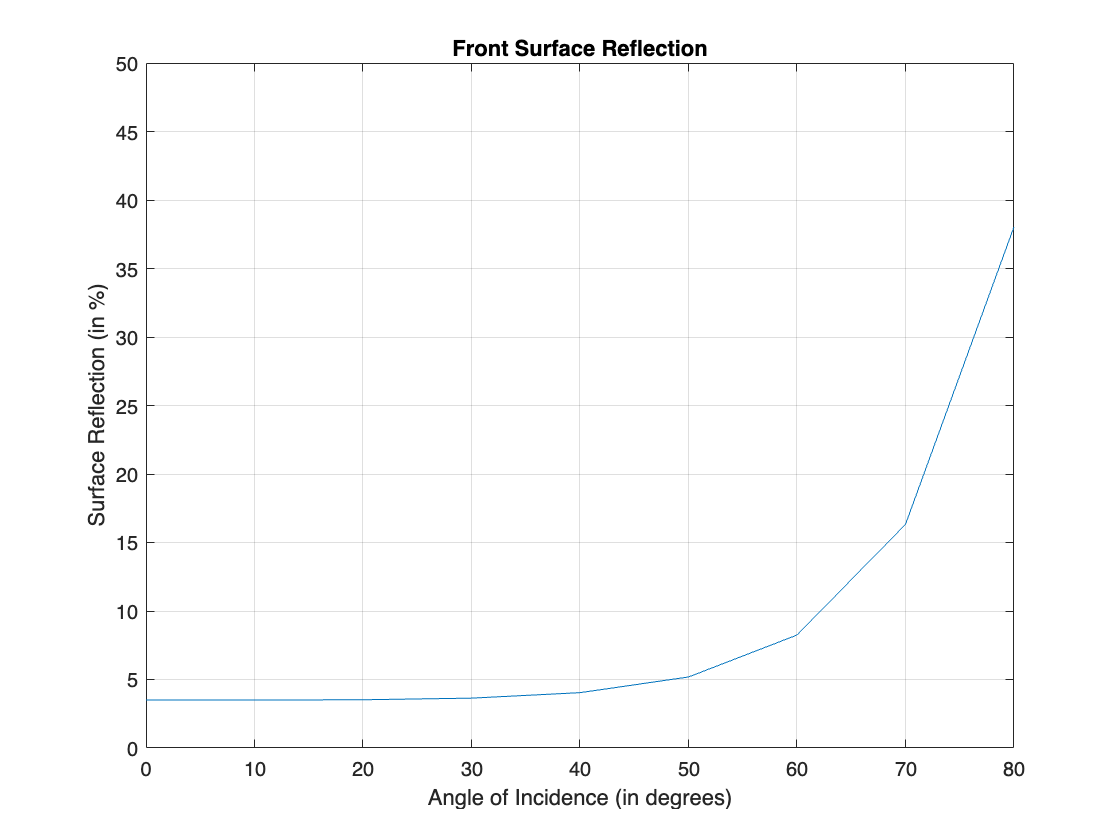

h = figure;
plot(angle_incidence,surface_reflection)
grid on

datacursormode(h,'on');
xlabel('Angle of Incidence (in degrees)')
ylabel('Surface Reflection (in %)')
title('Front Surface Reflection')
ylim([0 50])

**Question 2b**

Compute the unpolarized front surface reflection in percent for angles of incidence of 0, 10, ..., 80° from normal, and plot the results as a function of angle